%% Dependencies
% Brain connectivity toolbox:
% download from https://www.nitrc.org/projects/bct/

%% input variables from developing_fingerprint_input.mat

% subjects selected for functional and structural data differ, hence the
% ages are different.

%FC_subn: 3D matrix size 90x90x62, where x and y represent functional connectivity between 90 GM nodes and z 1:31 represents the subjects at timepoint 1, and 32:61 at timepoint 2.
%SC_subn: 3D matrix size 90x90x90, where x and y represent structural connectivity between 90 GM nodes and z 1:45 represents the subjects at timepoint 1, and 46:90 at timepoint 2.
%ga_simm_FC: vector where 1:31 represents age at birth of subjects with functional data, 32:61 repeats the values for consistency with pma vector size.   
%ga_simm_SC: vector where 1:45 represents age at birth of subjects with structural data, 46:90 repeats the values for consistency with pma vector size.
%pma_simm_FC: vector where 1:31 represents the postmenstrual age at first scan of subjects with functional data, and 32:61 represents the postmenstrual age at second scan.
%pma_simm_SC: vector where 45:90 represents the postmenstrual age at first scan of subjects with structural data, and 46:90 represents the postmenstrual age at second scan.

clear all;
load developing_fingerprint_input.mat;

%% STRUCTURAL AND FUNCTIONAL DATA - calculate days between scans

% SC
n=length(pma_simm_SC)/2;
for s=1:n
    for s2=1:n
    days_sc1_sc2_SC(s,s2)=(pma_simm_SC(s2+n)-pma_simm_SC(s))/(1/7);
    end
end

% FC
n=length(pma_simm_FC)/2;
for s=1:n
    for s2=1:n
    days_sc1_sc2_FC(s,s2)=(pma_simm_FC(s2+n)-pma_simm_FC(s))/(1/7);
    end
end

%% simmilarity matrix

% test proportion of weights to preserve p=1 (all weights preserved) to p=0 (no weights preserved)

n_sc=(size(SC_subn,3)/2);
thr=0.01:0.01:1;

for s=1:n_sc

    disp(['Processing subject ',num2str(s),'/',num2str(n_sc),'...']);

    for s2=1:n_sc
        for t=1:length(thr)
            thr_aux=thr(t);
            % if using a fixed threshold fix thr_aux 
            % e.g.: thr_aux=0.5;

            aux_connect_tp1_SC(:,:)=threshold_proportional(SC_subn(:,:,s),thr_aux);
            aux_connect_tp2_SC(:,:)=SC_subn(:,:,s2+n_sc);

            % use mask at tp1 when thresholding each domain:
            mask_SC_t1=tril(aux_connect_tp1_SC(:,:)>0);
            simm_SC(s,s2,t)=corr(aux_connect_tp1_SC(mask_SC_t1>0),aux_connect_tp2_SC(mask_SC_t1>0),'type','Spearman');

        end
    end
end

Processing subject 1/45...
Processing subject 2/45...
Processing subject 3/45...
Processing subject 4/45...
Processing subject 5/45...
Processing subject 6/45...
Processing subject 7/45...
Processing subject 8/45...
Processing subject 9/45...
Processing subject 10/45...
Processing subject 11/45...
Processing subject 12/45...
Processing subject 13/45...
Processing subject 14/45...
Processing subject 15/45...
Processing subject 16/45...
Processing subject 17/45...
Processing subject 18/45...
Processing subject 19/45...
Processing subject 20/45...
Processing subject 21/45...
Processing subject 22/45...
Processing subject 23/45...
Processing subject 24/45...
Processing subject 25/45...
Processing subject 26/45...
Processing subject 27/45...
Processing subject 28/45...
Processing subject 29/45...
Processing subject 30/45...
Processing subject 31/45...
Processing subject 32/45...
Processing subject 33/45...
Processing subject 34/45...
Processing subject 35/45...
Processing subject 36/45...
P




n_fc=(size(FC_subn,3)/2);

for s=1:n_fc
    disp(['Processing subject ',num2str(s),'/',num2str(n_fc),'...']);
    
    for s2=1:n_fc
        for t=1:length(thr)
            thr_aux=thr(t);
            % if using a fixed threshold 
            % thr_aux=0.5;

            aux_connect_tp1_FC(:,:)=threshold_proportional(FC_subn(:,:,s),thr_aux);
            aux_connect_tp2_FC(:,:)=FC_subn(:,:,s2+n_fc);

            % use mask at tp1 when thresholding each domain
            mask_FC_t1=tril(aux_connect_tp1_FC(:,:)>0);
            simm_FC(s,s2,t)=corr(aux_connect_tp1_FC(mask_SC_t1>0),aux_connect_tp2_FC(mask_SC_t1>0),'type','Spearman');
        end
    end
end

Processing subject 1/31...
Processing subject 2/31...
Processing subject 3/31...
Processing subject 4/31...
Processing subject 5/31...
Processing subject 6/31...
Processing subject 7/31...
Processing subject 8/31...
Processing subject 9/31...
Processing subject 10/31...
Processing subject 11/31...
Processing subject 12/31...
Processing subject 13/31...
Processing subject 14/31...
Processing subject 15/31...
Processing subject 16/31...
Processing subject 17/31...
Processing subject 18/31...
Processing subject 19/31...
Processing subject 20/31...
Processing subject 21/31...
Processing subject 22/31...
Processing subject 23/31...
Processing subject 24/31...
Processing subject 25/31...
Processing subject 26/31...
Processing subject 27/31...
Processing subject 28/31...
Processing subject 29/31...
Processing subject 30/31...
Processing subject 31/31...


clear aux*

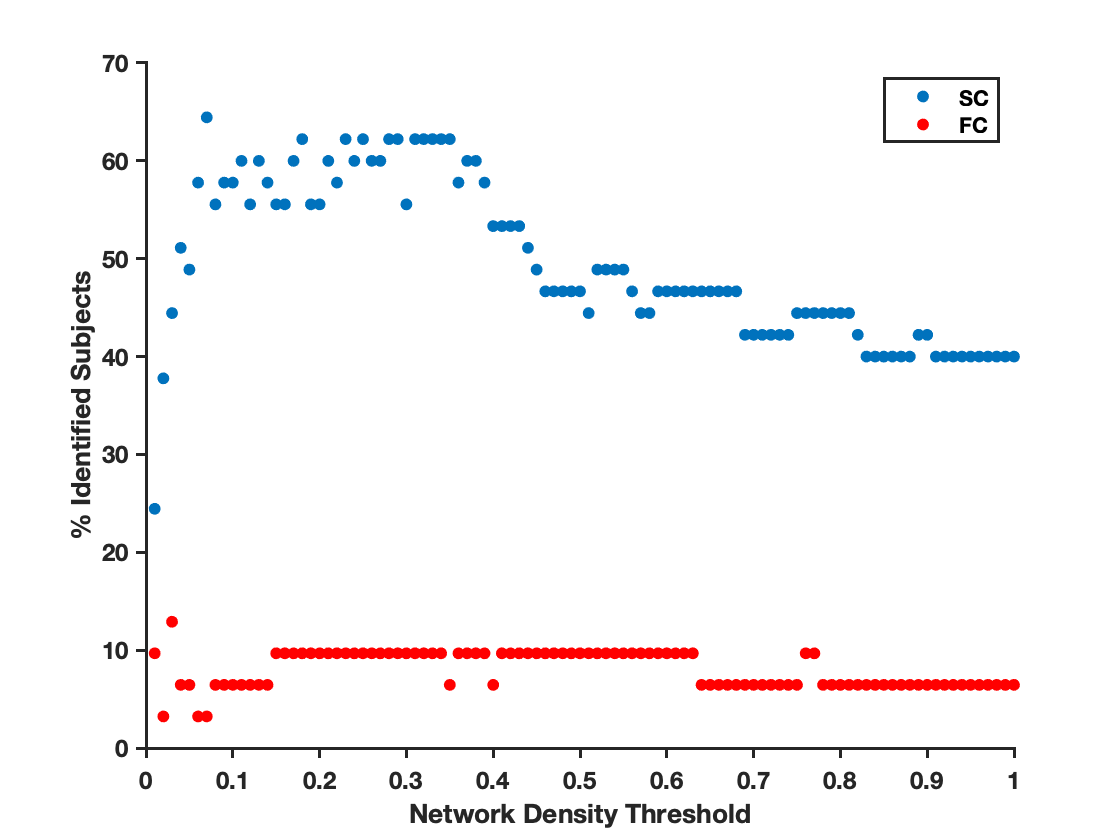

%% global success rate and identifiability

for n=1:length(thr)
    temp_sim_sc=simm_SC(:,:,n);
    temp_sim_fc=simm_FC(:,:,n);
    clear count_sc
    clear count_fc

    count_sc=0;
    Diagii_sc=diag(temp_sim_sc);

    count_fc=0;
    Diagii_fc=diag(temp_sim_fc);

    for i=1:n_sc
        if Diagii_sc(i)==max(temp_sim_sc(i,:))
            count_sc=count_sc+1;
        end
    end

    for i=1:n_fc
        if Diagii_fc(i)==max(temp_sim_fc(i,:))
            count_fc=count_fc+1;
        end
    end

    succes_rate_sc(n)=count_sc;
    succes_rate_fc(n)=count_fc;

end

succes_rate_sc_percent=(succes_rate_sc*100)/n_sc;
succes_rate_fc_percent=(succes_rate_fc*100)/n_fc;

figure
title('Network Density Dependent Fingerprint')
plot(thr, succes_rate_sc_percent,'.','MarkerSize',16)
hold on
plot(thr, succes_rate_fc_percent,'.','color','r','MarkerSize',16)
set(gca,'TickDir','out','box','off','linewidth',1.5,'FontSize', 12,'fontweight','bold')
legend({'SC','FC'},'Location','northeast')
xlabel('Network Density Threshold') 
ylabel('% Identified Subjects') 

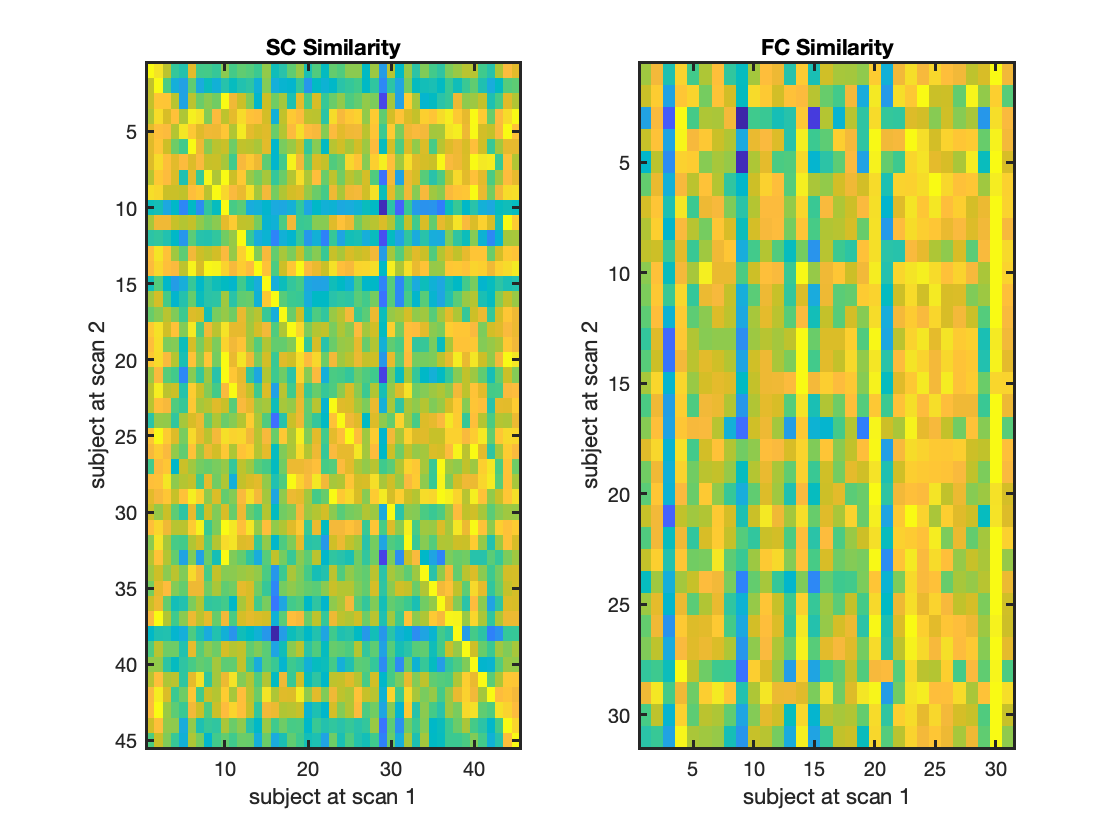

    
%% threshold selected 0.25
sim_sc_fin=simm_SC(:,:,25);
sim_fc_fin=simm_FC(:,:,25);
     
%% visualization with simmilarity scaled to max 1

for n=1:length(sim_fc_fin)
    FCcorrMax_global(n,:)=sim_fc_fin(n,:)./max(sim_fc_fin(n,:));    
end

for n=1:length(sim_sc_fin)
    SCcorrMax_global(n,:)=sim_sc_fin(n,:)./max(sim_sc_fin(n,:));
end

figure;
subplot(1,2,1);imagesc(SCcorrMax_global); set(gca,'linewidth',1.5); xlabel('subject at scan 1'); ylabel('subject at scan 2'); title({'SC Similarity'})
subplot(1,2,2);imagesc(FCcorrMax_global);set(gca,'linewidth',1.5); xlabel('subject at scan 1'); ylabel('subject at scan 2'); title({'FC Similarity'})